一、

（1）

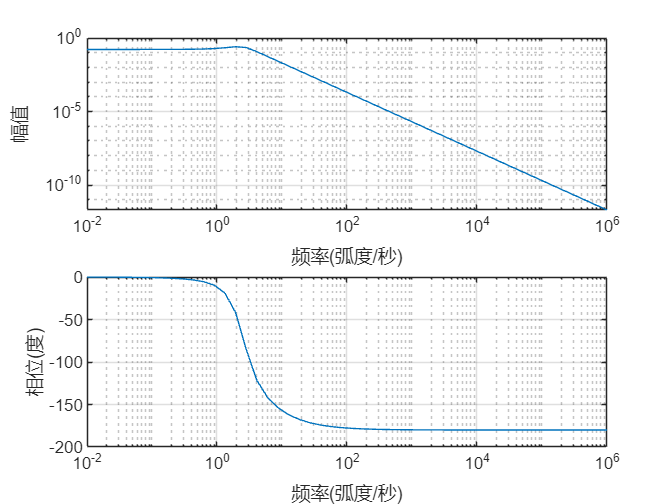

num=[2,4];
den=[1,6,15,24];
w=logspace(-2,6);
figure(1);
freqs(num,den,w);

这是一个低通系统

(2)

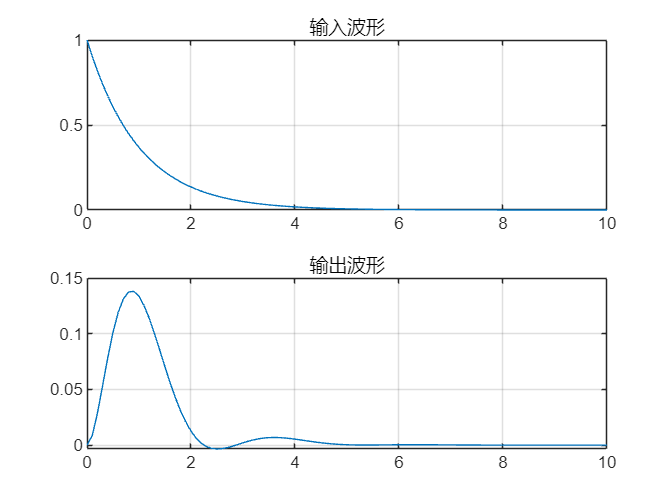

t=0:0.1:10;
x=exp(-t);
y=lsim(num,den,x,t);
figure(2);
subplot(2,1,1);
plot(t,x);
title('输入波形');
grid on;
subplot(2,1,2);
plot(t,y);
title('输出波形');
grid on;

二、

1.

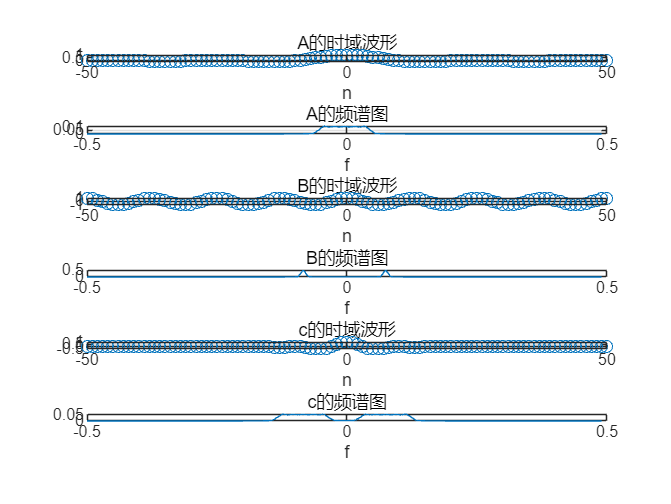

n=-50:50;
x=sinc(0.1*n);
s=cos(0.5*n);
e=x.*s;
L=length(n);
w=(-L/2:L/2-1)/L;
figure(3);
subplot(6,1,1);
stem(n,x);
xlabel('n');
ylabel('x');
title('A的时域波形');
grid on;
subplot(6,1,2);
f=fft(x,L);
ft=fftshift(f);
plot(w,abs(ft/L));
xlabel('f');
ylabel('|A|');
title('A的频谱图');
grid on;


subplot(6,1,3);
stem(n,s);
xlabel('n');
ylabel('s');
title('B的时域波形');
grid on;
subplot(6,1,4);
f=fft(s,L);
ft=fftshift(f);
plot(w,abs(ft/L));
xlabel('f');
ylabel('|A|');
title('B的频谱图');
grid on;


subplot(6,1,5);
stem(n,e);
xlabel('n');
ylabel('e');
title('c的时域波形');
grid on;
subplot(6,1,6);
f=fft(e,L);
ft=fftshift(f);
plot(w,abs(ft/L));
xlabel('f');
ylabel('|A|');
title('c的频谱图');
grid on;

2.

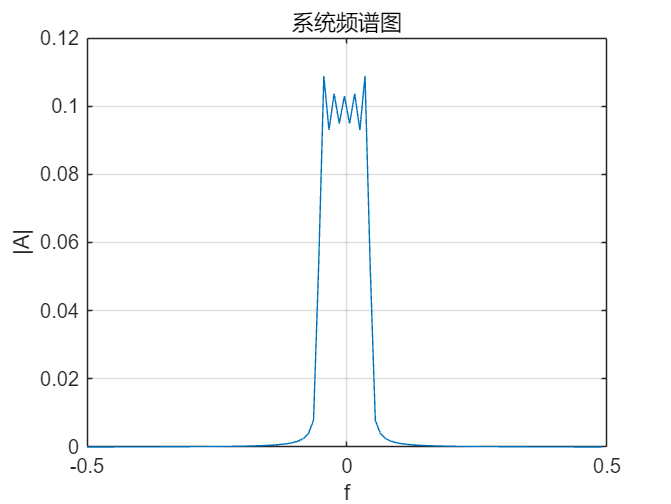

n=0:100;
h=sinc(0.1*(n-50));
figure(4);
f=fft(h,L);
ft=fftshift(f);
plot(w,abs(ft/L));
xlabel('f');
ylabel('|A|');
title('系统频谱图');
grid on;

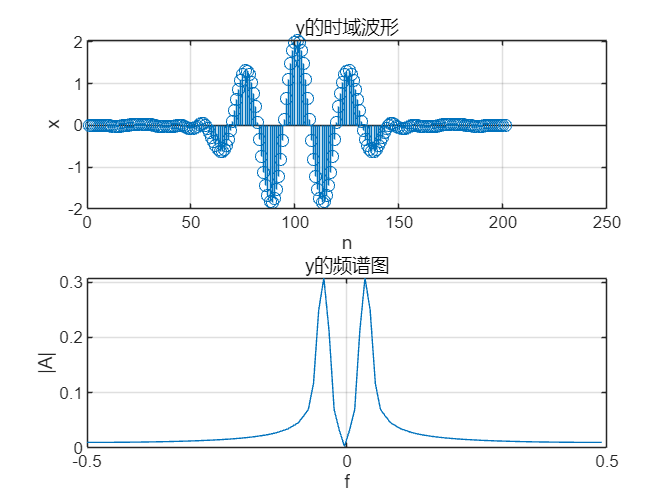


y=conv(h,e);
figure(5);
subplot(2,1,1);
stem(y);
xlabel('n');
ylabel('x');
title('y的时域波形');
grid on;
subplot(2,1,2);
f=fft(y,L);
ft=fftshift(f);
plot(w,abs(ft/L));
xlabel('f');
ylabel('|A|');
title('y的频谱图');
grid on;

3.

这是一个低通系统,yn是sa信号